clear all
gamma_A = 0.5;   gamma_B = 0.5;  

% Transcription rate/ Production rate:
g_A =10; 
g_B = 10;   

% Hills function threshold :
A0B = 2;
B0A = 2;
A0A = 12;   B0B = 12;

% Cooperativity/ hill function coefficient:
nAtoB = 5;   nBtoA = 5;
nAtoA = 4;   nBtoB = 4;

% fold change/ lambda
lambda_AtoB = 0.1;   lambda_BtoA = 0.1;
lambda_AtoA = 3;   lambda_BtoB = 3;

S=[gamma_A;gamma_B;g_A;g_B;A0B;B0A;A0A;B0B;nAtoB;nBtoA;nAtoA;nBtoB;lambda_AtoB;lambda_BtoA;lambda_AtoA;lambda_BtoB];
param_1=[S(3)-1*S(3):0.05*S(3): 1.9*S(3)];
param_2=[S(5)-1*S(5):0.05*S(5): 1.9*S(5)];

stability=zeros(length(param_1),length(param_2));

domain = [0 500];
times=50;


for m=1:length(param_1)
    for n=1:length(param_2)
        states=[];
        states=[0];
        for i=1:1:times
            flag=0;
            A = 10*rand(1);
            B = 10*rand(1);
            S_curr=S;
            S_curr(3)=param_1(m);
            S_curr(5)=param_2(n);
            [t, x] = ode45(@(t,x) interactions(t,x,S_curr),domain,[A;B]);
            final_state=x(end,:);
            for j=1:1:length(states)
                curr=states(j);
                if (0.7*curr<=final_state(1))&&(final_state(1)<=1.3*curr)
                    flag=1;
                end
            end
            if flag==0
                states=[states;final_state(1)];
            end
        end
        stability(m,n)=length(states)-1;
    end
end

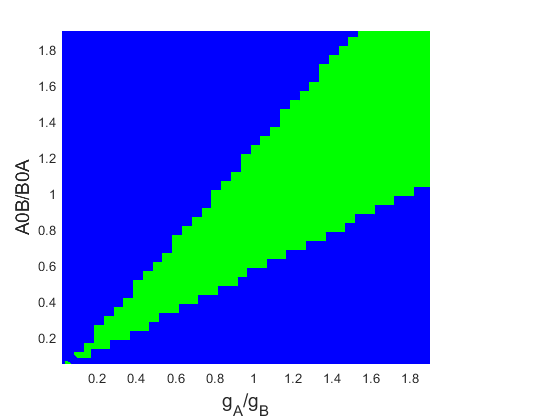




 mymap=[ 0 0 1
         0 1 0
         1 0 0];
param_1=param_1./S(4);
param_2=param_2./S(6);
surf(param_1,param_2,stability,'EdgeColor','none'), colormap(mymap),grid off,shading interp,caxis([1,3]), 

view([0.4 90.0])
ylim([(min(param_2)+0.05) max(param_2)])
xlim([(min(param_1)+0.02) max(param_1)])
colorbar
ylabel('A0B/B0A',"FontSize",14,"FontWeight","bold","FontName",'Arial')
xlabel('g_A/g_B',"FontSize",14,"FontWeight","bold","FontName",'Arial')
colorbar off


legend off


function H = hill(X,X0,lambda,n)
% H+ 
H1 = (X^n)/(X0^n+X^n);
% H-
H2 = (X0^n)/(X0^n+X^n);

% Hill function =  H- plus (lambda)* H+
H = H2 + lambda*H1;

end



function dxdt = interactions(t,x,S)

% defining array of values for the time t: 
dxdt = zeros(2,1);

%% Paramaters
% Degradation rate:
gamma_A = S(1);   gamma_B = S(2);  

% Transcription rate/ Production rate:
g_A =S(3); 
g_B = S(4);   

% Hills function threshold :
A0B =  S(5);
B0A =  S(6);
A0A = S(7);   B0B=S(8);

% Cooperativity/ hill function coefficient:
nAtoB = S(9);   nBtoA = S(10);
nAtoA = S(11);   nBtoB = S(12);

% fold change/ lambda
lambda_AtoB = S(13);  lambda_BtoA = S(14);
lambda_AtoA =S(15);  lambda_BtoB =S(16);

% %% equations:
% dxdt(1) = g_A*hill(x(1),A0A,lambda_AtoA,nAtoA)*hill(x(2),B0A,lambda_BtoA,nBtoA) - gamma_A*x(1);  %% equation A
% dxdt(2) = g_B*hill(x(2),B0B,lambda_BtoB,nBtoB)*hill(x(1),A0B,lambda_AtoB,nAtoB) - gamma_B*x(2); % equation B
% end
dxdt(1) = g_A*hill(x(2),B0A,lambda_BtoA,nBtoA) - gamma_A*x(1) ;  %% equation A
dxdt(2) = g_B*hill(x(1),A0B,lambda_AtoB,nAtoB) - gamma_B*x(2) ; % equation B
end


        